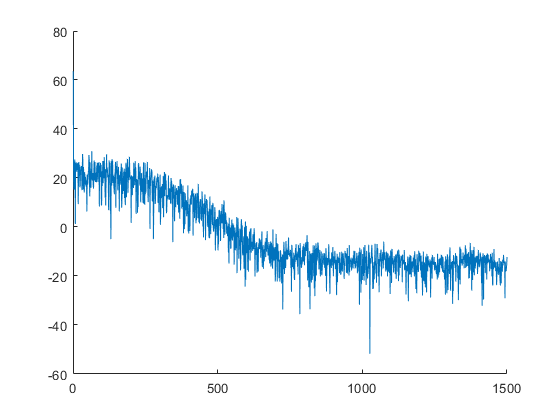

clear all
close all
clc

rng(4);

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',10);


% plot(inz)

FY = mag2db(abs(fft(inz)));

figure;
hold on
plot(FY(1:floor(end/2)))
hold off


% Choose TT-ranks

n=3; m=3;
mn = n+m;

inlags=[1 2];
outlags =[0 1 2 4 8];

d=numel(inlags)+numel(outlags)-1;
% r = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxrank));

synth = double(rand(mn*ones(1,d))>0.5);

% for i=1:d
% synth = (smoothdata(synth,i,'gaussian',3));
% end

TN = ttsvd(synth,0.001)

TN = struct with fields:
    core: {[1×6×6 double]  [6×6×36 double]  [36×6×195 double]  [195×6×36 double]  [36×6×6 double]  [6×6 double]}
      sz: [6×3 double]


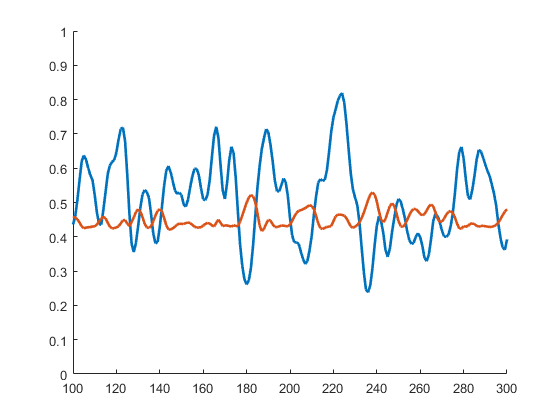


siminput = inz;
siminput(1:21)=heaviside(-10:10)/2;

simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth',2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([100 300 0 1])

noiso = 0.000001;

  
noize = noiso*randn(size(simoutput));
simoutputnoise = simoutput+ noize;
simoutputnoise(simoutputnoise>1) = 1;
simoutputnoise(simoutputnoise<0) = 0;
SNR = snr(simoutput(10:end)-mean(simoutput(10:end)),noize(10:end))

SNR = 87.4840


% figure
% hold on
% % plot(siminput)
% plot(simoutput,'Linewidth',2)
% plot(simoutputnoise)
% % plot((inz(11)/simoutput(11))*simoutput)
% hold off
% axis([0 200 -inf inf])



input = siminput(10:2000);
output = simoutputnoise(10:2000);
outputclean = simoutput(10:2000);

tinput = siminput(2001:end);
toutput = simoutput(2001:end);
toutputnoise = simoutputnoise(2001:end);


% plot(uEst)
% plot(yEst)
% for i =1:7
% uEst = [uEst ;(uEst+0.0*rand(size(uEst)))];
% yEst = [yEst ;(yEst+0.5*rand(size(yEst)))];
% end
% 
% yEst(yEst>10)=10;
% plot(uVal)
% plot(yVal)

% autocorr(uEst,1000)
% autocorr(yEst,1000)

% parcorr(uEst,1000)
% parcorr(yEst,1000)

Preprocessing Data

tic

% Choose the lags for the input
inlags=[1 2];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-(1900):end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-(900):end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2 4 8];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-(1900):end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-(900):end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 3;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train -----------------------------------------------------------------


for period= 1:10
% Choose TT-ranks
maxrank =period;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

rez = [];

Compression: 0.0007716


Compression: 0.002572


Compression: 0.0054012


Compression: 0.0092593


Compression: 0.014146


Compression: 0.020062


Compression: 0.024949


Compression: 0.03035


Compression: 0.036265


Compression: 0.042695


Optimize TT cores

lambda=1*10^-4;
gamma=0;

difforder=2;
MAXITR = 4*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.036036"

    "iteration:"    "2"    "0.045072"

    "iteration:"    "3"    "0.049075"

    "iteration:"    "4"    "0.051669"

    "iteration:"    "5"    "0.054147"

    "iteration:"    "6"    "0.057838"

    "iteration:"    "7"    "0.060233"

    "iteration:"    "8"    "0.06286"

    "iteration:"    "9"    "0.065566"

    "iteration:"    "10"    "0.068347"

    "iteration:"    "11"    "0.073818"

    "iteration:"    "12"    "0.07632"

    "iteration:"    "13"    "0.078748"

    "iteration:"    "14"    "0.081064"

    "iteration:"    "15"    "0.083347"

    "iteration:"    "16"    "0.085703"

    "iteration:"    "17"    "0.088001"

    "iteration:"    "18"    "0.090577"

    "iteration:"    "19"    "0.092918"

    "iteration:"    "20"    "0.095191"

    "iteration:"    "21"    "0.097464"

    "iteration:"    "22"    "0.099779"

    "iteration:"    "23"    "0.10202"

    "iteration:"    "24"    "0.10427"



    "iteration:"    "1"    "0.028001"

    "iteration:"    "2"    "0.041514"

    "iteration:"    "3"    "0.050694"

    "iteration:"    "4"    "0.062754"

    "iteration:"    "5"    "0.069469"

    "iteration:"    "6"    "0.076162"

    "iteration:"    "7"    "0.082546"

    "iteration:"    "8"    "0.093203"

    "iteration:"    "9"    "0.098789"

    "iteration:"    "10"    "0.11067"

    "iteration:"    "11"    "0.11854"

    "iteration:"    "12"    "0.12737"

    "iteration:"    "13"    "0.134"

    "iteration:"    "14"    "0.14047"

    "iteration:"    "15"    "0.14679"

    "iteration:"    "16"    "0.15219"

    "iteration:"    "17"    "0.15781"

    "iteration:"    "18"    "0.16161"

    "iteration:"    "19"    "0.1694"

    "iteration:"    "20"    "0.17718"

    "iteration:"    "21"    "0.18339"

    "iteration:"    "22"    "0.19214"

    "iteration:"    "23"    "0.20319"

    "iteration:"    "24"    "0.21234"



    "iteration:"    "1"    "0.018752"

    "iteration:"    "2"    "0.031073"

    "iteration:"    "3"    "0.041282"

    "iteration:"    "4"    "0.050968"

    "iteration:"    "5"    "0.063132"

    "iteration:"    "6"    "0.075304"

    "iteration:"    "7"    "0.087407"

    "iteration:"    "8"    "0.09718"

    "iteration:"    "9"    "0.10888"

    "iteration:"    "10"    "0.11841"

    "iteration:"    "11"    "0.12955"

    "iteration:"    "12"    "0.14366"

    "iteration:"    "13"    "0.15618"

    "iteration:"    "14"    "0.16592"

    "iteration:"    "15"    "0.17935"

    "iteration:"    "16"    "0.19087"

    "iteration:"    "17"    "0.20035"

    "iteration:"    "18"    "0.21179"

    "iteration:"    "19"    "0.22101"

    "iteration:"    "20"    "0.2337"

    "iteration:"    "21"    "0.24639"

    "iteration:"    "22"    "0.25581"

    "iteration:"    "23"    "0.26757"

    "iteration:"    "24"    "0.27731"



    "iteration:"    "1"    "0.016485"

    "iteration:"    "2"    "0.045761"

    "iteration:"    "3"    "0.077111"

    "iteration:"    "4"    "0.098261"

    "iteration:"    "5"    "0.11834"

    "iteration:"    "6"    "0.13759"

    "iteration:"    "7"    "0.15827"

    "iteration:"    "8"    "0.17646"

    "iteration:"    "9"    "0.19483"

    "iteration:"    "10"    "0.21317"

    "iteration:"    "11"    "0.27699"

    "iteration:"    "12"    "0.29848"

    "iteration:"    "13"    "0.31979"

    "iteration:"    "14"    "0.33853"

    "iteration:"    "15"    "0.35678"

    "iteration:"    "16"    "0.37655"

    "iteration:"    "17"    "0.39615"

    "iteration:"    "18"    "0.41306"

    "iteration:"    "19"    "0.44283"

    "iteration:"    "20"    "0.48556"

    "iteration:"    "21"    "0.50569"

    "iteration:"    "22"    "0.52425"

    "iteration:"    "23"    "0.54496"

    "iteration:"    "24"    "0.56344"



    "iteration:"    "1"    "0.034993"

    "iteration:"    "2"    "0.062597"

    "iteration:"    "3"    "0.094631"

    "iteration:"    "4"    "0.18811"

    "iteration:"    "5"    "0.23289"

    "iteration:"    "6"    "0.26332"

    "iteration:"    "7"    "0.29359"

    "iteration:"    "8"    "0.32101"

    "iteration:"    "9"    "0.35163"

    "iteration:"    "10"    "0.38124"

    "iteration:"    "11"    "0.41125"

    "iteration:"    "12"    "0.43802"

    "iteration:"    "13"    "0.4687"

    "iteration:"    "14"    "0.4987"

    "iteration:"    "15"    "0.52908"

    "iteration:"    "16"    "0.55557"

    "iteration:"    "17"    "0.58302"

    "iteration:"    "18"    "0.61039"

    "iteration:"    "19"    "0.64043"

    "iteration:"    "20"    "0.66695"

    "iteration:"    "21"    "0.69952"

    "iteration:"    "22"    "0.73803"

    "iteration:"    "23"    "0.76617"

    "iteration:"    "24"    "0.79268"



    "iteration:"    "1"    "0.048421"

    "iteration:"    "2"    "0.099981"

    "iteration:"    "3"    "0.15613"

    "iteration:"    "4"    "0.20491"

    "iteration:"    "5"    "0.26933"

    "iteration:"    "6"    "0.32115"

    "iteration:"    "7"    "0.36428"

    "iteration:"    "8"    "0.41304"

    "iteration:"    "9"    "0.45941"

    "iteration:"    "10"    "0.50214"

    "iteration:"    "11"    "0.54637"

    "iteration:"    "12"    "0.59112"

    "iteration:"    "13"    "0.63119"

    "iteration:"    "14"    "0.67536"

    "iteration:"    "15"    "0.72178"

    "iteration:"    "16"    "0.76975"

    "iteration:"    "17"    "0.81498"

    "iteration:"    "18"    "0.8575"

    "iteration:"    "19"    "0.89686"

    "iteration:"    "20"    "0.94287"

    "iteration:"    "21"    "0.99353"

    "iteration:"    "22"    "1.0396"

    "iteration:"    "23"    "1.0895"

    "iteration:"    "24"    "1.1422"



    "iteration:"    "1"    "0.073246"

    "iteration:"    "2"    "0.15442"

    "iteration:"    "3"    "0.26807"

    "iteration:"    "4"    "0.33572"

    "iteration:"    "5"    "0.40552"

    "iteration:"    "6"    "0.47622"

    "iteration:"    "7"    "0.54118"

    "iteration:"    "8"    "0.60128"

    "iteration:"    "9"    "0.67258"

    "iteration:"    "10"    "0.73228"

    "iteration:"    "11"    "0.7972"

    "iteration:"    "12"    "0.859"

    "iteration:"    "13"    "0.93004"

    "iteration:"    "14"    "0.99824"

    "iteration:"    "15"    "1.0666"

    "iteration:"    "16"    "1.1272"

    "iteration:"    "17"    "1.1938"

    "iteration:"    "18"    "1.2554"

    "iteration:"    "19"    "1.3204"

    "iteration:"    "20"    "1.3873"

    "iteration:"    "21"    "1.4497"

    "iteration:"    "22"    "1.5104"

    "iteration:"    "23"    "1.578"

    "iteration:"    "24"    "1.6371"



    "iteration:"    "1"    "0.14882"

    "iteration:"    "2"    "0.24693"

    "iteration:"    "3"    "0.3367"

    "iteration:"    "4"    "0.43474"

    "iteration:"    "5"    "0.5212"

    "iteration:"    "6"    "0.61982"

    "iteration:"    "7"    "0.70921"

    "iteration:"    "8"    "0.80769"

    "iteration:"    "9"    "0.89484"

    "iteration:"    "10"    "0.99541"

    "iteration:"    "11"    "1.0872"

    "iteration:"    "12"    "1.1882"

    "iteration:"    "13"    "1.2794"

    "iteration:"    "14"    "1.3804"

    "iteration:"    "15"    "1.4715"

    "iteration:"    "16"    "1.5728"

    "iteration:"    "17"    "1.6634"

    "iteration:"    "18"    "1.7643"

    "iteration:"    "19"    "1.8545"

    "iteration:"    "20"    "1.9552"

    "iteration:"    "21"    "2.045"

    "iteration:"    "22"    "2.1476"

    "iteration:"    "23"    "2.2611"

    "iteration:"    "24"    "2.377"



    "iteration:"    "1"    "0.15922"

    "iteration:"    "2"    "0.30313"

    "iteration:"    "3"    "0.4468"

    "iteration:"    "4"    "0.58853"

    "iteration:"    "5"    "0.73299"

    "iteration:"    "6"    "0.87485"

    "iteration:"    "7"    "1.0157"

    "iteration:"    "8"    "1.1604"

    "iteration:"    "9"    "1.3294"

    "iteration:"    "10"    "1.4847"

    "iteration:"    "11"    "1.6303"

    "iteration:"    "12"    "1.7761"

    "iteration:"    "13"    "1.9204"

    "iteration:"    "14"    "2.0708"

    "iteration:"    "15"    "2.25"

    "iteration:"    "16"    "2.3996"

    "iteration:"    "17"    "2.5649"

    "iteration:"    "18"    "2.724"

    "iteration:"    "19"    "2.8869"

    "iteration:"    "20"    "3.0355"

    "iteration:"    "21"    "3.2641"

    "iteration:"    "22"    "3.4411"

    "iteration:"    "23"    "3.5818"

    "iteration:"    "24"    "3.7234"



    "iteration:"    "1"    "0.21026"

    "iteration:"    "2"    "0.4886"

    "iteration:"    "3"    "0.6844"

    "iteration:"    "4"    "0.88809"

    "iteration:"    "5"    "1.0939"

    "iteration:"    "6"    "1.2935"

    "iteration:"    "7"    "1.5068"

    "iteration:"    "8"    "1.7135"

    "iteration:"    "9"    "1.9546"

    "iteration:"    "10"    "2.1517"

    "iteration:"    "11"    "2.3513"

    "iteration:"    "12"    "2.5585"

    "iteration:"    "13"    "2.7752"

    "iteration:"    "14"    "2.976"

    "iteration:"    "15"    "3.1671"

    "iteration:"    "16"    "3.3637"

    "iteration:"    "17"    "3.5612"

    "iteration:"    "18"    "3.7685"

    "iteration:"    "19"    "3.9843"

    "iteration:"    "20"    "4.191"

    "iteration:"    "21"    "4.4073"

    "iteration:"    "22"    "4.6147"

    "iteration:"    "23"    "4.8175"

    "iteration:"    "24"    "5.0274"



rez = [rez res1];
% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)

% plot(rez)

Evaluate Test data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% % plot(zeta)
% plot(outputclean(end-1900:end))
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



% 
% yhat = evalspline(TN,tfeaturez,n,m);
% erboi = (yhat-yt);
% % histogram((erboi)');
% VAF = 1-var(erboi)/var(yt)
% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 inf -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


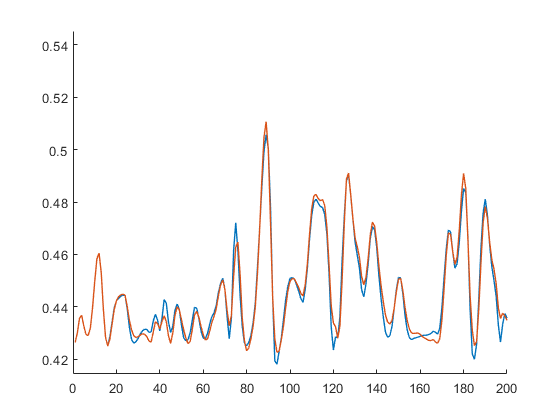

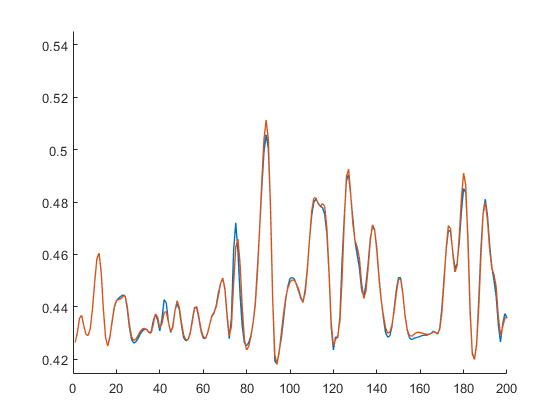

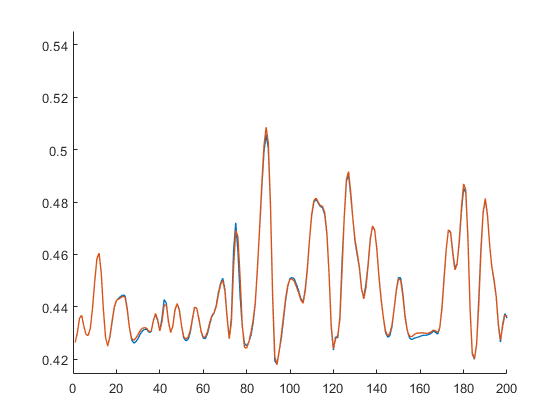

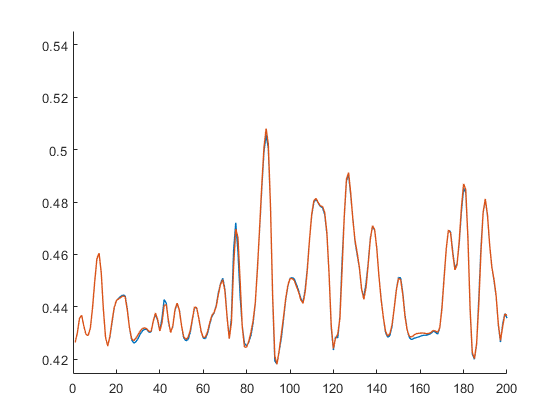

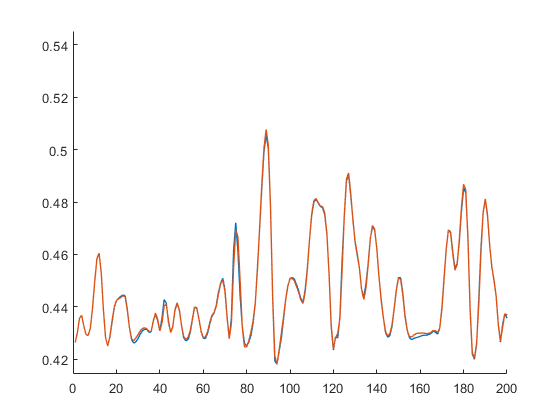

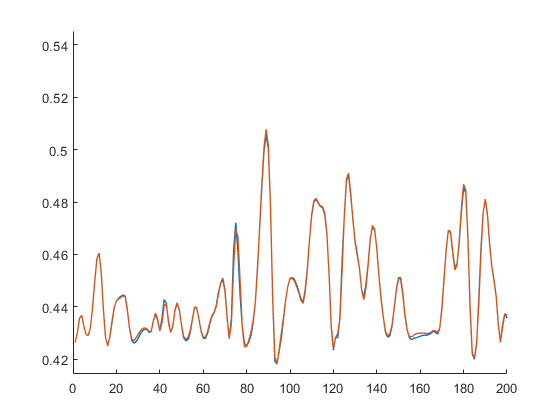

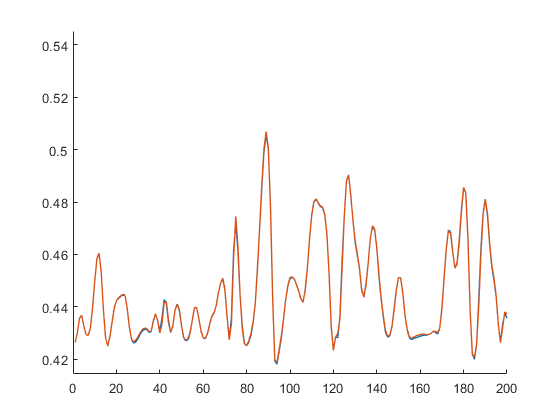

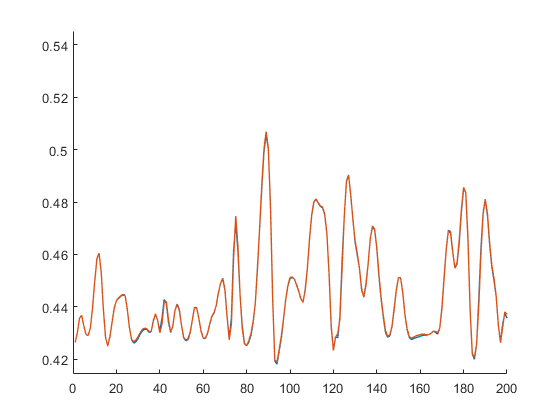

% plot(tinput)
% plot(toutput)

siminputz = tinput;
simoutputz = toutput;
numz = numel(outlags);
for j = 17:1000
simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutputz(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
% plot(toutputnoise)
plot(toutput,'Linewidth',1)
plot(simoutputz,'Linewidth',1)
hold off
axis([0 200 -inf inf])


RMSE(period) = sqrt(immse(toutput,simoutputz));

RMSE = 0.0037

RMSE =     0.0037    0.0023


RMSE =     0.0037    0.0023    0.0012


RMSE =     0.0037    0.0023    0.0012    0.0011


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011    0.0011


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011    0.0011    0.0007


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011    0.0011    0.0007    0.0007


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011    0.0011    0.0007    0.0007    0.0007


RMSE =     0.0037    0.0023    0.0012    0.0011    0.0011    0.0011    0.0007    0.0007    0.0007    0.0007


VAF(period) = 1-var(toutput-simoutputz)/var(toutput);

VAF = 0.9701

VAF =     0.9701    0.9885


VAF =     0.9701    0.9885    0.9969


VAF =     0.9701    0.9885    0.9969    0.9973


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973    0.9974


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973    0.9974    0.9988


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973    0.9974    0.9988    0.9988


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973    0.9974    0.9988    0.9988    0.9990


VAF =     0.9701    0.9885    0.9969    0.9973    0.9973    0.9974    0.9988    0.9988    0.9990    0.9991


end
toc

Elapsed time is 5.271428 seconds.


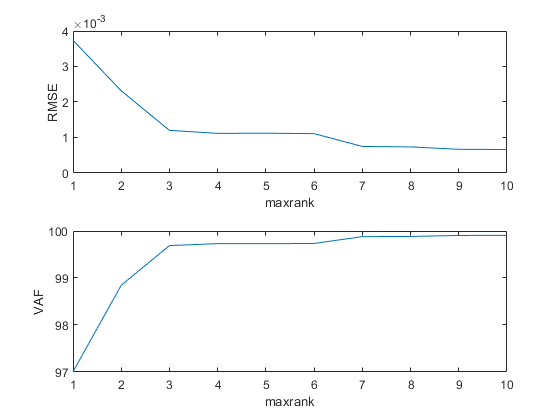

subplot(2,1,1)
plot(1:10,RMSE)
xlabel('maxrank')
ylabel('RMSE')

subplot(2,1,2)
plot(1:10,VAF*100)

xlabel('maxrank')
ylabel('VAF')